fis = readfis('FuzzyLogic.fis');
sug_fis = convertToSugeno(fis);

%needs to be done after converted to sugeno
fis = convertToStruct(fis);

fis

% Generate random input data
num_samples = 100;
input_data = rand(num_samples, 5); % Random input data with 5 inputs

% Apply the FIS to get the output
output_data = zeros(num_samples, 3); % Preallocate output data
for i = 1:num_samples
    output_data(i, :) = evalfis(input_data(i, :), fis);
end

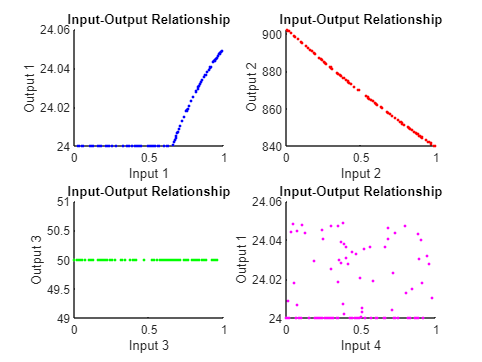


% Plot the input-output relationship
figure;
subplot(2, 2, 1);
scatter(input_data(:, 1), output_data(:, 1), 'b.');
xlabel('Input 1');
ylabel('Output 1');
title('Input-Output Relationship');

subplot(2, 2, 2);
scatter(input_data(:, 2), output_data(:, 2), 'r.');
xlabel('Input 2');
ylabel('Output 2');
title('Input-Output Relationship');

subplot(2, 2, 3);
scatter(input_data(:, 3), output_data(:, 3), 'g.');
xlabel('Input 3');
ylabel('Output 3');
title('Input-Output Relationship');

subplot(2, 2, 4);
scatter(input_data(:, 4), output_data(:, 1), 'm.');
xlabel('Input 4');
ylabel('Output 1');
title('Input-Output Relationship');

Let's start the optimization

% Define GA parameters
population_size = 50;
num_generations = 100;
mutation_rate = 0.1;

% Initialize population
num_variables = 5; % Assuming all inputs have the same number of membership functions
chromosome_length = 3 * num_variables * 3; % Assuming 3 membership functions for each input variable
population = rand(population_size, chromosome_length);

% Define input-output data (replace with your actual dataset)
input_data = [1, 2, 3, 4, 5]; % Example input data
output_data = [0.2, 0.4, 0.6, 0.8, 1]; % Example output data

% Genetic Algorithm Parameters
population_size = 50;
num_generations = 100;
mutation_rate = 0.1;

% Define lower and upper bounds for parameter optimization
lower_bound = [0 0]; % Lower bounds for membership functions
upper_bound = [10 10]; % Upper bounds for membership functions

% Define fitness function
fitness_function = @(x) evaluate_fitness(fis, input_data, output_data, x);

% Perform optimization using genetic algorithm
options = optimoptions('ga', 'PopulationSize', population_size, 'MaxGenerations', num_generations, 'MutationFcn', {@mutationadaptfeasible, mutation_rate});

Error using optimoptions
ga requires Global Optimization Toolbox.

[opt_params, opt_fitness] = ga(fitness_function, 2, [], [], [], [], lower_bound, upper_bound, [], options);

disp('Optimal parameters:');
disp(opt_params);
disp('Optimal fitness:');
disp(opt_fitness);

% Function to evaluate fitness

function fitness = evaluate_fitness(fis, input_data, output_data, params)
    % Update membership functions based on the parameters
    updated_fis = update_membership_functions(fis, params);
    
    % Evaluate FLC performance using input-output data
    output = evalfis(input_data, updated_fis);
    
    % Calculate fitness (e.g., mean squared error)
    fitness = -mean((output - output_data).^2); % Negative MSE to maximize fitness
end

% Function to update membership functions
function updated_fis = update_membership_functions(fis, params)
    % Update membership functions of input variables
    fis.input(1).mf(1).params = params(1);
    fis.input(1).mf(2).params = params(2);
    
    % Update membership functions of output variables
    % Modify according to your FIS structure
    
    updated_fis = fis;
end